clear; clc; close all;

warning('off','all')

%% 1. CARGAR MODELO RANDOM FOREST ENTRENADO
modeloFile = 'modelo_random_forest.mat';

if isfile(modeloFile)
    data = load(modeloFile); 
    
    % Buscar automáticamente un modelo que sea un objeto con método 'predict'
    campos = fieldnames(data);
    encontrado = false;
    for i = 1:length(campos)
        candidato = data.(campos{i});
        if isobject(candidato) && ismethod(candidato, 'predict')
            modeloFinal_RF = candidato;
            encontrado = true;
            fprintf('\n✅ Modelo cargado: "%s"\n', campos{i});
            break;
        end
    end
    
    if ~encontrado
        error('❌ El archivo existe pero no contiene un modelo de clasificación válido.');
    end
else
    error('❌ No se encontró el archivo "%s". Entrena y guarda el modelo primero.', modeloFile);
end


✅ Modelo cargado: "modelo_rf"


%% 2. SELECCIÓN DE CARPETA CON IMÁGENES
carpeta = uigetdir('', 'Selecciona la carpeta con imágenes');
if carpeta == 0
    error('No se seleccionó ninguna carpeta. Abortando.');
end

extensiones = {'*.jpg','*.jpeg','*.png','*.tif','*.tiff'};
archivos = [];
for k = 1:numel(extensiones)
    archivos = [archivos; dir(fullfile(carpeta, extensiones{k}))];
end

if isempty(archivos)
    error('No se encontraron imágenes en la carpeta seleccionada.');
end

%% 3. PROCESAR TODAS LAS IMÁGENES
tablaResumen = table();

for i = 1:length(archivos)
    nombreImagen = archivos(i).name;
    rutaImagen = fullfile(carpeta, nombreImagen);

    fprintf('\n📷 Procesando imagen: %s\n', nombreImagen);
    tablaResultados = analizarImagenIndividual(rutaImagen);

    % Verificar predictores del modelo
    if isprop(modeloFinal_RF, 'PredictorNames')
        varsParaModelo = modeloFinal_RF.PredictorNames;
    else
        error('El modelo cargado no contiene información sobre las variables predictoras.');
    end

    faltantes = setdiff(varsParaModelo, tablaResultados.Properties.VariableNames);
    if ~isempty(faltantes)
        error('Faltan columnas para predecir: %s', strjoin(faltantes, ', '));
    end

    X_test = normalize(tablaResultados{:, varsParaModelo});
    [y_pred_cell, ~] = predict(modeloFinal_RF, X_test);
    y_pred = categorical(y_pred_cell);

    % Contar clases predichas
    clases = lower(string(y_pred));
    numParasitos = sum(clases == "parasito");
    numGlobulosBlancos = sum(clases == "globuloblanco");
    
    if numGlobulosBlancos == 0
        razon = Inf;
    else
        razon = numParasitos / numGlobulosBlancos;
    end

    umbralInfeccion = 0.05;
    if razon >= umbralInfeccion
        estado = "Muestra infectada por malaria";
    else
        estado = "Muestra sana";
    end

    % Añadir fila al resumen
    nuevaFila = table({nombreImagen}, numParasitos, numGlobulosBlancos, razon, estado, ...
                      'VariableNames', {'NombreImagen', 'NumParasitos', 'NumGB', 'RazonPporGB', 'Estado'});
    tablaResumen = [tablaResumen; nuevaFila];
end


📷 Procesando imagen: 20170607_143659.jpg

📷 Procesando imagen: 20170607_144600.jpg

📷 Procesando imagen: 20170607_160355.jpg

📷 Procesando imagen: 20170705_111253.jpg

📷 Procesando imagen: 20170705_111649.jpg

📷 Procesando imagen: 20170725_151827.jpg

📷 Procesando imagen: 20170727_182921.jpg

📷 Procesando imagen: 20170811_153539.jpg

📷 Procesando imagen: 20170820_152020.jpg

📷 Procesando imagen: 20170831_103804.jpg

📷 Procesando imagen: 20170831_103857.jpg

📷 Procesando imagen: 20170831_104152.jpg

📷 Procesando imagen: 20171023_110309.jpg

📷 Procesando imagen: 20171023_113206.jpg

📷 Procesando imagen: 20171023_124359.jpg

📷 Procesando imagen: 20171023_132520.jpg

📷 Procesando imagen: 20171023_142559.jpg

📷 Procesando imagen: 20171023_152939.jpg

📷 Procesando imagen: 20171023_154703.jpg

📷 Procesando imagen: 20190404_152850.jpg

📷 Procesando imagen: 20190404_155619.jpg

📷 Procesando imagen: 20190405_152824.jpg

📷 Procesando imagen: 20190405_161815.jpg

📷 Procesando imagen: 20190410_164


%% 4. MOSTRAR TABLA FINAL
fprintf('\n📊 Resumen por imagen:\n');


📊 Resumen por imagen:


disp(tablaResumen);

          NombreImagen          NumParasitos    NumGB    RazonPporGB                Estado             
    ________________________    ____________    _____    ___________    _______________________________

    {'20170607_143659.jpg' }          2          31       0.064516      "Muestra infectada por malaria"
    {'20170607_144600.jpg' }          3          28        0.10714      "Muestra infectada por malaria"
    {'20170607_160355.jpg' }          0          22              0      "Muestra sana"                 
    {'20170705_111253.jpg' }          0          14              0      "Muestra sana"                 
    {'20170705_111649.jpg' }          0          34              0      "Muestra sana"                 
    {'20170725_151827.jpg' }         11          24        0.45833      "Muestra infectada por malari

Si P/GB > 0.05 --> muestra infectada de malaria // Si P/GB < 0.05 --> muestra sana

% Seleccionar carpeta con los archivos .txt 
folderPath = uigetdir('', 'Selecciona la carpeta con los archivos .txt');

if folderPath == 0
    error('No se seleccionó ninguna carpeta. Abortando.');
end

% Obtener lista de archivos .txt
archivos = dir(fullfile(folderPath, '*.txt'));

% Inicializar resultados
n = length(archivos);
nombres = cell(n,1);
estado = cell(n,1);

% Etiquetas que indican parásitos
etiquetasParasito = {'Parasite', 'Parasitized'};

for i = 1:n
    try
        nombreArchivo = archivos(i).name;
        rutaArchivo = fullfile(folderPath, nombreArchivo);

        % Leer todo el archivo línea por línea
        fid = fopen(rutaArchivo, 'r');
        if fid == -1
            warning('No se pudo abrir el archivo: %s', nombreArchivo);
            continue;
        end

        hayParasito = false;
        while ~feof(fid)
            linea = fgetl(fid);
            partes = strsplit(linea, ',');
            if length(partes) >= 2
                etiqueta = strtrim(partes{2});  % Segundo campo
                if any(strcmpi(etiqueta, etiquetasParasito))
                    hayParasito = true;
                    break;  % No hace falta seguir leyendo
                end
            end
        end
        fclose(fid);

        % Guardar diagnóstico
        nombres{i} = nombreArchivo;
        if hayParasito
            estado{i} = 'Muestra infectada por malaria';
        else
            estado{i} = 'Muestra sana';
        end

    catch ME
        warning('⚠️ Error procesando el archivo %s: %s', archivos(i).name, ME.message);
    end
end

% Crear tabla final
tablaDiagnostico = table(nombres, estado, ...
                         'VariableNames', {'NombreImagen', 'Estado'});

% Mostrar resultados
disp(tablaDiagnostico);

         NombreImagen                       Estado              
    _______________________    _________________________________

    {'20170607_143659.txt'}    {'Muestra infectada por malaria'}
    {'20170607_144600.txt'}    {'Muestra infectada por malaria'}
    {'20170607_160355.txt'}    {'Muestra infectada por malaria'}
    {'20170705_111253.txt'}    {'Muestra infectada por malaria'}
    {'20170705_111649.txt'}    {'Muestra infectada por malaria'}
    {'20170725_151827.txt'}    {'Muestra infectada por malaria'}
    {'20170727_182921.txt'}    {'Muestra infectada por malaria'}
    {'20170728_201358.txt'}    {'Muestra sana'                 }
    {'20170728_212318.txt'}    {'Muestra sana'                 }
    {'20170807_100003.txt'}    {'Muestra sana'                 }
    {'20170811_153539.txt'}    {'Muestra infectada por malaria'}
    {'20170816_113729.txt'}    {'Muestra sana'                 }
    {'20170816_113834

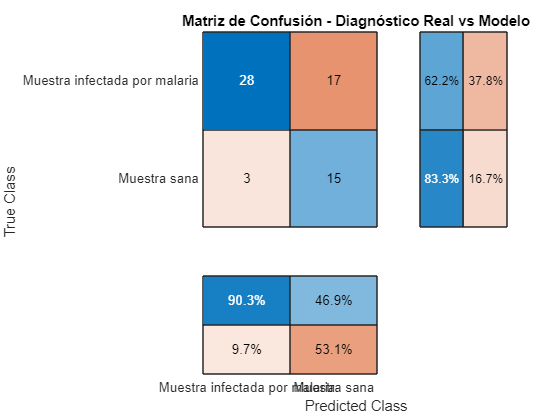

% 1. Obtener nombres sin extensión (minúsculas por si hay mayúsculas)
nombres_resumen = lower(erase(tablaResumen.NombreImagen, {'.jpg', '.tiff'}));
nombres_diagnostico = lower(erase(tablaDiagnostico.NombreImagen, '.txt'));

% 2. Inicializar etiquetas para comparación
estado_modelo = strings(0,1); 
estado_real   = strings(0,1); 

% 3. Comparar uno a uno
for i = 1:length(nombres_resumen)
    nombre = nombres_resumen{i};
    idx = find(strcmp(nombres_diagnostico, nombre));

    if ~isempty(idx)
        estado_modelo(end+1) = tablaResumen.Estado(i);
        estado_real(end+1)   = tablaDiagnostico.Estado{idx};
    else
        warning('⚠️ No se encontró diagnóstico real para: %s', tablaResumen.NombreImagen{i});
    end
end

% 4. Validación
if isempty(estado_real)
    error('❌ No se pudo emparejar ninguna imagen con su diagnóstico correspondiente.');
end

% 5. Mostrar matriz de confusión
figure;
confusionchart(estado_real, estado_modelo, ...
    'Title', 'Matriz de Confusión - Diagnóstico Real vs Modelo', ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');


% 6. Calcular y mostrar precisión (accuracy)
accuracy = mean(estado_modelo == estado_real);
fprintf('\n✅ Precisión (accuracy) del modelo comparado con el diagnóstico real: %.2f%%\n', 100 * accuracy);


✅ Precisión (accuracy) del modelo comparado con el diagnóstico real: 68.25%


% Etiquetas verdaderas binarizadas
labels = strcmpi(estado_real, 'Muestra infectada por malaria');

% Scores de probabilidad (razón P/GB)
scores = zeros(length(estado_real), 1);
for i = 1:length(estado_real)
    nombre = nombres_diagnostico{strcmp(nombres_diagnostico, nombres_resumen{i})};
    idx = find(strcmpi(tablaResumen.NombreImagen, [nombre, '.jpg']) | ...
               strcmpi(tablaResumen.NombreImagen, [nombre, '.tiff']));
    if ~isempty(idx)
        scores(i) = tablaResumen.RazonPporGB(idx);
    else
        scores(i) = 0;
    end
end

% Curva ROC
[rocX, rocY, ~, AUC] = perfcurve(labels, scores, true);

% Predicciones binarias usando umbral 0.05
umbral = 0.05;
pred_binarias = scores >= umbral;

% Métricas
TP = sum(pred_binarias == 1 & labels == 1);
TN = sum(pred_binarias == 0 & labels == 0);
FP = sum(pred_binarias == 1 & labels == 0);
FN = sum(pred_binarias == 0 & labels == 1);

accuracy = (TP + TN) / (TP + TN + FP + FN);
precision = TP / (TP + FP);
recall = TP / (TP + FN); 

% Mostrar métricas
fprintf('\n📊 Métricas Seleccionadas:\n');


📊 Métricas Seleccionadas:


fprintf('✔️ Accuracy     : %.2f%%\n', 100 * accuracy);

✔️ Accuracy     : 49.66%


fprintf('✔️ Precision    : %.2f%%\n', 100 * precision);

✔️ Precision    : 71.43%


fprintf('✔️ Sensibilidad : %.2f%%\n', 100 * recall);

✔️ Sensibilidad : 49.21%


fprintf('✔️ AUC (ROC)    : %.2f\n', AUC);

✔️ AUC (ROC)    : 0.71


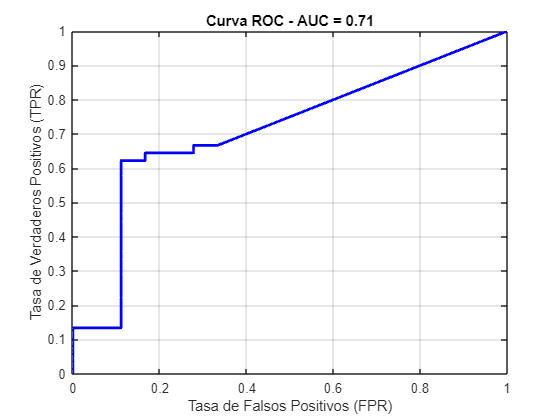


% Graficar curva ROC
figure;
plot(rocX, rocY, 'b-', 'LineWidth', 2);
xlabel('Tasa de Falsos Positivos (FPR)');
ylabel('Tasa de Verdaderos Positivos (TPR)');
title(sprintf('Curva ROC - AUC = %.2f', AUC));
grid on;

function tabla = analizarImagenIndividual(imgPath)
    [~, nombreImagen, ext] = fileparts(imgPath);
    nombreArchivo = [nombreImagen, ext];
    
    IPF = imread(imgPath);
    Imagen_FILT = im2double(IPF);    
    I_gray = rgb2gray(Imagen_FILT);

    Imagen_mascara_gray = rgb2gray(cat(3, IPF(:,:,1), IPF(:,:,2), zeros(size(IPF(:,:,1)))));
    fov_mask = segmentCellsStainBased(Imagen_mascara_gray);

    OD = -log(Imagen_FILT + 0.01);
    OD = reshape(OD, [], 3);
    W_manual = [
        0.650, 0.072, 0.707;
        0.704, 0.990, 0.707;
        0.286, 0.117, 0.000
    ];
    W = W_manual ./ vecnorm(W_manual, 2, 2);
    W = W';
    C = OD * inv(W);
    deconvolved_manual = reshape(C, size(IPF));
    Imagen_nucleos = deconvolved_manual(:,:,3);

    bw = imbinarize(Imagen_nucleos);
    Imagen_masked = bw .* fov_mask;

    imagenEcualizada = adapthisteq(I_gray);
    mascaraPortaobjetos = imbinarize(imagenEcualizada, graythresh(imagenEcualizada));
    mascaraPortaobjetos = imfill(mascaraPortaobjetos, 'holes');
    mascaraPortaobjetos = bwareafilt(mascaraPortaobjetos, 1);
    imagenEcualizada(~mascaraPortaobjetos) = 0;

    pixelesDentroFOV = imagenEcualizada(fov_mask);
    umbralOscuridad = prctile(pixelesDentroFOV, 5);
    mascaraOscuros = imagenEcualizada < umbralOscuridad;
    mascaraOscuros = mascaraOscuros & logical(fov_mask);

    areaMinimaGlobulos = 1800;
    mascaraGB = bwareafilt(mascaraOscuros, [areaMinimaGlobulos Inf]);

    elementoEstructurante = strel('disk', 15);
    mascaraGBdilatada = imdilate(mascaraGB, elementoEstructurante);

    imagenSinGB = Imagen_masked;
    imagenSinGB(mascaraGBdilatada) = 0;
    imagenSegmentable = uint8(imagenSinGB);

    umbralGlobal = graythresh(imagenSegmentable);
    mascaraOtros = imbinarize(imagenSegmentable, umbralGlobal);
    mascaraOtros = filtrar_por_tamano(mascaraOtros, 400);  

    mascaraTotal = mascaraGB | mascaraOtros;

    tabla = calcularCaracteristicas(mascaraTotal, IPF, nombreArchivo);
end

function fov_mask = segmentCellsStainBased(I)
    if size(I, 3) == 3
        I = rgb2gray(I);
    end
    level = graythresh(I);
    bw = imbinarize(I, level);
    if mean(I(bw)) < mean(I(~bw))
        bw = ~bw;
    end
    bw_clean = imopen(bw, strel('disk', 5));
    bw_clean = imclose(bw_clean, strel('disk', 5));
    bw_clean = imfill(bw_clean, 'holes');
    stats = regionprops(bw_clean, 'Area', 'Centroid', 'EquivDiameter');
    [~, idx] = max([stats.Area]);
    circle_centroid = stats(idx).Centroid;
    circle_radius = stats(idx).EquivDiameter / 2;
    adjusted_radius = max(circle_radius - 15, 0);
    [rows, cols] = size(bw_clean);
    [X, Y] = meshgrid(1:cols, 1:rows);
    fov_mask = (X - circle_centroid(1)).^2 + (Y - circle_centroid(2)).^2 <= adjusted_radius^2;
end

function salida = filtrar_por_tamano(imagen_binaria, umbral_max)
    componentes = bwlabel(imagen_binaria);
    stats = regionprops(componentes, 'Area');
    salida = ismember(componentes, find([stats.Area] <= umbral_max));
end

function tabla = calcularCaracteristicas(mascara, imagen, nombreImagen)
    props = regionprops(mascara, 'Area', 'Perimeter', 'PixelIdxList');
    n = length(props);

    if n == 0
        tabla = table();
        return;
    end

    % Canales RGB
    R = imagen(:,:,1);
    G = imagen(:,:,2);
    B = imagen(:,:,3);

    % Inicializar vectores
    Area = [props.Area]';
    Perimetro = [props.Perimeter]';
    Circularidad = zeros(n, 1);
    IntensidadR = zeros(n, 1);
    IntensidadG = zeros(n, 1);
    IntensidadB = zeros(n, 1);

    for i = 1:n
        A = props(i).Area;
        P = props(i).Perimeter;
        Circularidad(i) = (P > 0) * (4 * pi * A / (P^2));

        idx = props(i).PixelIdxList;
        IntensidadR(i) = mean(R(idx));
        IntensidadG(i) = mean(G(idx));
        IntensidadB(i) = mean(B(idx));
    end

    IntensidadRGBMedia = mean([IntensidadR, IntensidadG, IntensidadB], 2);
    NombreImagen = repmat({nombreImagen}, n, 1);
    GroupCount = ones(n, 1);

    % Construir tabla final
    tabla = table(NombreImagen, GroupCount, ...
                  Area, Perimetro, Circularidad, ...
                  IntensidadR, IntensidadG, IntensidadB, IntensidadRGBMedia);

    varsNumericas = varfun(@isnumeric, tabla, 'OutputFormat', 'uniform');

    % Renombrar variables según espera el modelo
    tabla.Properties.VariableNames{'Area'} = 'mean_Area';
    tabla.Properties.VariableNames{'Perimetro'} = 'mean_Perimetro';
    tabla.Properties.VariableNames{'Circularidad'} = 'mean_Circularidad';
    tabla.Properties.VariableNames{'IntensidadR'} = 'mean_IntensidadR';
    tabla.Properties.VariableNames{'IntensidadG'} = 'mean_IntensidadG';
    tabla.Properties.VariableNames{'IntensidadB'} = 'mean_IntensidadB';
    tabla.Properties.VariableNames{'IntensidadRGBMedia'} = 'mean_IntensidadRGBMedia';
end